### Demonstrate various  image enhancement techniques using Built-in and user defined functions

#### BUILT-IN FUNCTIONS

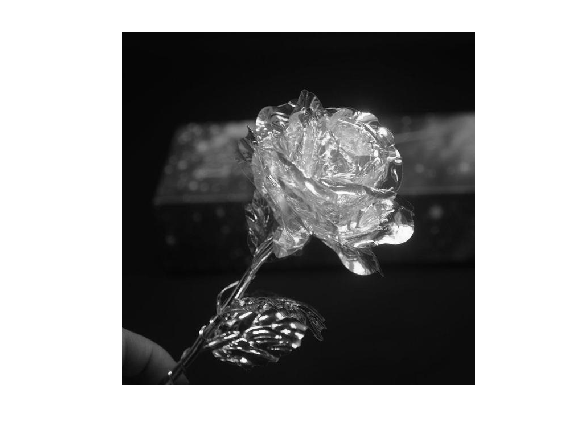

%Selecting an image
clf;
originalImage = imread('ROSE.jpg');
bin = rgb2gray(originalImage);
imshow(bin)

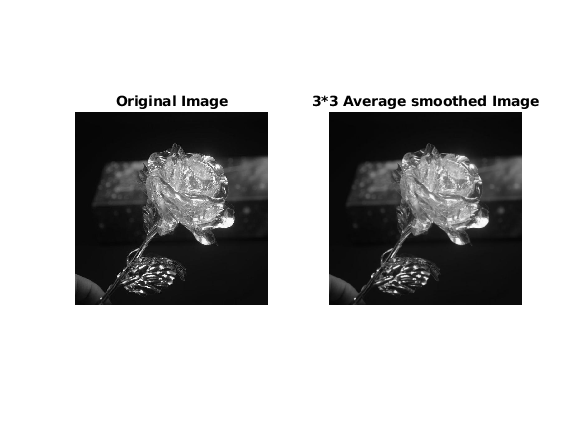

%AVERAGE FILTERNIG
%img = imread(bin);
imgd = im2double(bin);   % imgd in [0,1]
f = ones(3,3)/9;
img1 = filter2(f, imgd,"valid" ); %Shape can be full/same/valid
subplot(121);imshow(imgd);title('Original Image')
subplot(122);imshow(img1);title('3*3 Average smoothed Image')

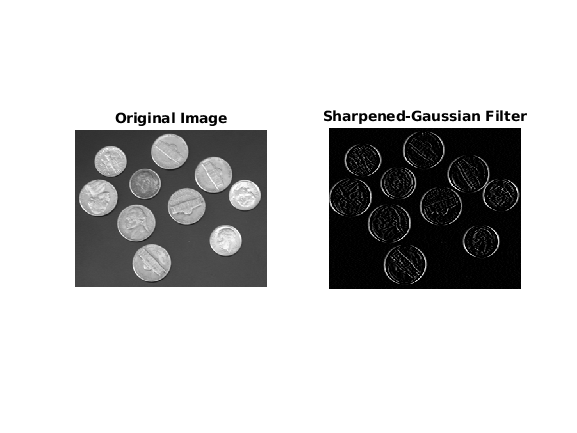

%GUASSIAN FILTERING
clf;
img = imread('coins.png');
imgd = im2double(img);   % imgd in [0,1]
f = [[0,1,0],[1,-4,1],[0,1,0]];
img1 = filter2(f, imgd,"valid" ); %Shape can be full/same/valid
subplot(121);imshow(img);title('Original Image')
subplot(122);imshow(img1);title('Sharpened-Gaussian Filter')

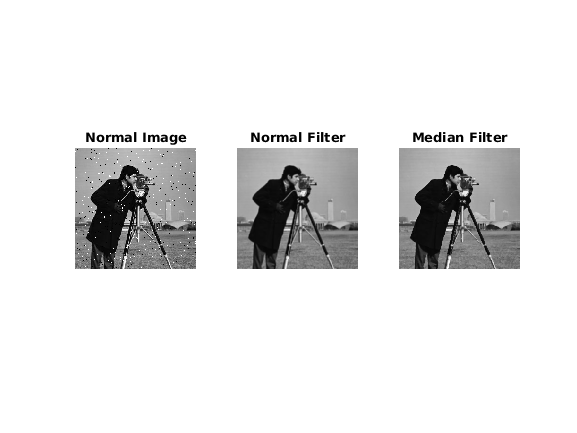

%Applying normal and median filter  to smooth the image to remove the salt pepper noise 
clf;
img = imread('cameraman.tif');
imgd = im2double(img);   % imgd in [0,1]
imgsp = imnoise(imgd,'salt & pepper',0.02);
f = ones(3,3)/9;
img1 = filter2(f, imgd); %Normal Filter Method
K = medfilt2(imgsp); %Median Fiter Method
subplot(1,3,1);imshow(imgsp);title('Normal Image')
subplot(1,3,2);imshow(img1);title('Normal Filter')
subplot(1,3,3);imshow(K);title('Median Filter')

**h=fspecial(value,parameter)**

**Value                                                                     Description**

average                                                               Averaging filter

disk                                                            Circular averaging filter (pillbox)

gaussian                                                        Gaussian lowpass filter

laplacian                                                        Laplacian of Gaussian filter

motion                                                Approximates the linear motion of a camera

prewitt                                                   Prewitt horizontal edge-emphasizing filter

sobel                                                       Sobel horizontal edge-emphasizing filter

**imfilter(A,h)**

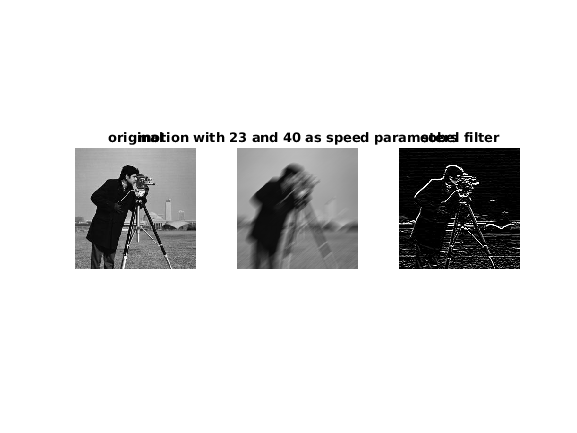

clf;
I = imread('cameraman.tif');
J1 = fspecial('motion', 23,40);
K1 = imfilter(I,J1,'replicate');
J10 = fspecial('sobel');
K10 = imfilter(I,J10,'replicate');
subplot(131);imshow(I);title('original');
subplot(132);imshow(K1);title('motion with 23 and 40 as speed parameters');
subplot(133);imshow(K10);title('sobel filter');

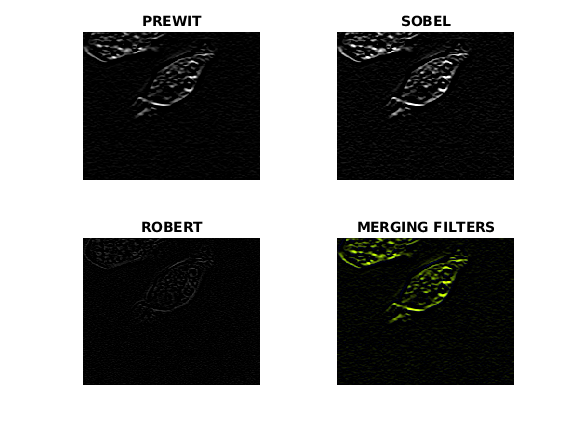

clf;
I = imread('cell.tif');
J1 = fspecial('prewit');
K1 = imfilter(I,J1,'replicate');
J2 = fspecial('sobel');
K2 = imfilter(I,J2,'replicate');
J3 = fspecial('laplacian');
K3 = imfilter(I,J3,'replicate');
subplot(221);imshow(K1);title('PREWIT');
subplot(222);imshow(K2);title('SOBEL');
subplot(223);imshow(K3);title('ROBERT');
FIN= cat(3,K1,K2,K3);
subplot(224);imshow(FIN);title('MERGING FILTERS')

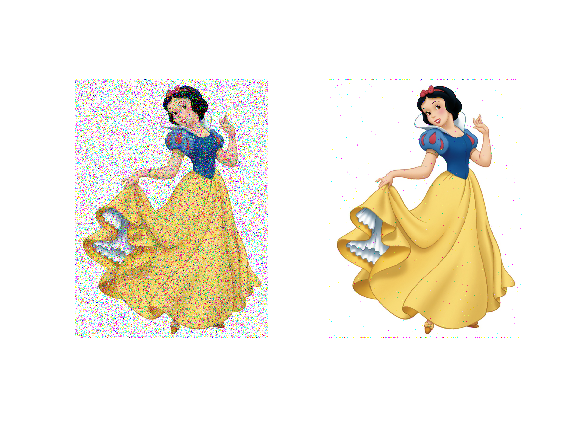

%COLOR IMAGE SMOOTHENING 
I = imread('SNOW_WHITE.jpg');
J = imnoise(I,'salt & pepper',0.2);
%Filter each channel separately
r = medfilt2(J(:, :, 1), [3 3]);
g = medfilt2(J(:, :, 2), [3 3]);
b = medfilt2(J(:, :, 3), [3 3]);
% reconstruct the image from r,g,b channels
K = cat(3,r,g,b);
figure
subplot(121);imshow(J);
subplot(122);imshow(K);

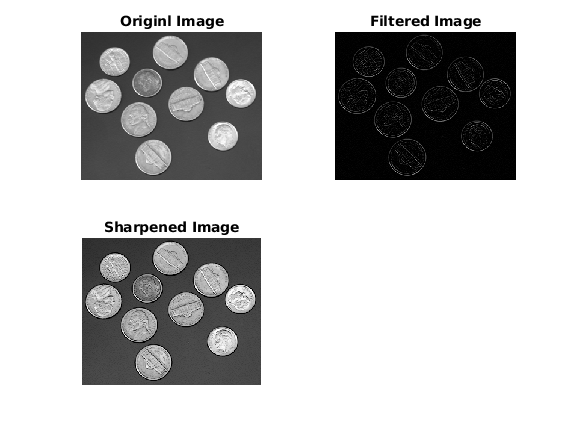

%Sharpening of the Image
%%Extra Methodology
A=imread('coins.png');
subplot(221);imshow(A);title('Originl Image')

%Preallocate the matrices with zeros
I1=A;
I=zeros(size(A));
I2=zeros(size(A));

%Filter Masks
F1=[0 1 0;1 -4 1; 0 1 0];
F2=[1 1 1;1 -8 1; 1 1 1];

%Padarray with zeros
A=padarray(A,[1,1]);
A=double(A);

for i=1:size(A,1)-2
    for j=1:size(A,2)-2
       
        I(i,j)=sum(sum(F1.*A(i:i+2,j:j+2)));
       
    end
end

I=uint8(I);
subplot(222);imshow(I);title('Filtered Image');


%Sharpenend Image
B=I1-I;
subplot(223);imshow(B);title('Sharpened Image');

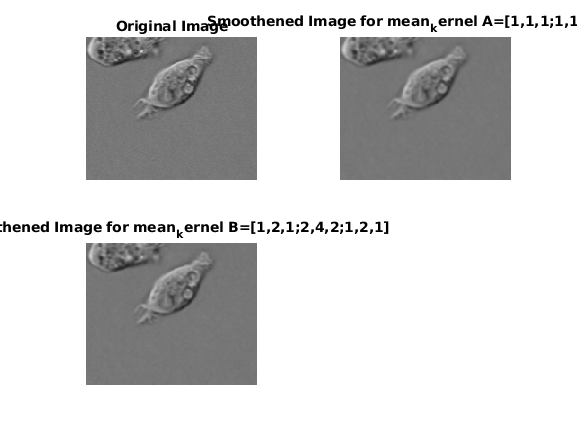

%User Defined function for smoothing image using average for
%weighted and non weighted kernel values
smooth_mean('cell.tif')

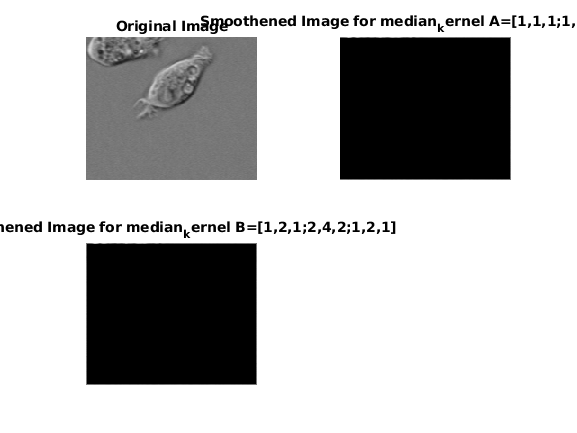

smooth_median('cell.tif')

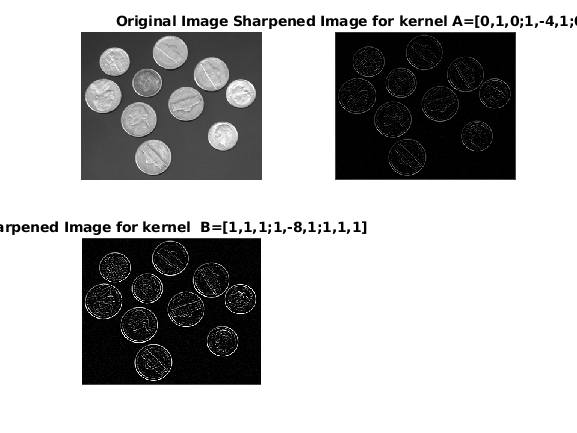

%User Defined function for sharpening image using Gaussian method
%For the 4 and 8 valued guassian filters
sharp('coins.png')

function pic=sharp(i)
%Sharpening the Image
clf;
F=double(imread(i));
H=F;
I=F;
[rows cols]=size(F);
 A=[0,1,0;1,-4,1;0,1,0];
 B=[1,1,1;1,-8,1;1,1,1];
G1=zeros(3,3);
G2=zeros(3,3);
for i = 2:rows-1
    for j = 2:cols-1
    
    for k=-1:1
        for l=-1:1
        G1(k+2,l+2)=F(i+k,j+l)*A(k+2,l+2);
        G2(k+2,l+2)=F(i+k,j+l)*B(k+2,l+2);
        end
    end
    H(i,j)=sum(sum(G1));
    I(i,j)=sum(sum(G2));
    end
end
H = uint8(round(H - 1));
I = uint8(round(I - 1));
figure()
subplot(2,2,1);
imshow(uint8(F));
title('Original Image');
subplot(2,2,2);
imshow(H);
title('Sharpened Image for kernel A=[0,1,0;1,-4,1;0,1,0]');
subplot(2,2,3);
imshow(I);
title('Sharpened Image for kernel  B=[1,1,1;1,-8,1;1,1,1]');
end







%Smoothening the image using mean method
function img=smooth_mean(x)
clf;
F=double(imread(x));
H=F;
I=F;
[rows cols]=size(F);
 A=[1,1,1;1,1,1;1,1,1];
 B=[1,2,1;2,4,2;1,2,1];
G1=zeros(3,3);
G2=zeros(3,3);
for i = 2:rows-1
    for j = 2:cols-1
    
    for k=-1:1
        for l=-1:1
        G1(k+2,l+2)=F(i+k,j+l).*A(k+2,l+2);
        G2(k+2,l+2)=F(i+k,j+l).*B(k+2,l+2);
        end
    end
    sumG1=sum(sum(G1));
    H(i,j)=sumG1./sum(sum(A));
    sumG2=sum(sum(G2));
    I(i,j)=sumG2./sum(sum(B));
    end
end
H = uint8(round(H - 1));
I = uint8(round(I - 1));
figure()
subplot(2,2,1);
imshow(uint8(F));
title('Original Image');
subplot(2,2,2);
imshow(H);
title('Smoothened Image for mean_kernel A=[1,1,1;1,1,1;1,1,1]');
subplot(2,2,3);
imshow(I);
title('Smoothened Image for mean_kernel B=[1,2,1;2,4,2;1,2,1]');
end







%Smoothening the image using median method
function img=smooth_median(x)
clf;
F=double(imread(x));
H=F;
I=F;
[rows cols]=size(F);
 A=[1,1,1;1,1,1;1,1,1];
 B=[1,2,1;2,4,2;1,2,1];
G1=zeros(3,3);
G2=zeros(3,3);
for i = 2:rows-1
    for j = 2:cols-1
    
    for k=-1:1
        for l=-1:1
        G1(k+2,l+2)=F(i+k,j+l).*A(k+2,l+2);
        G2(k+2,l+2)=F(i+k,j+l).*B(k+2,l+2);
        end
    end
    H(i,j)=median(median(A));
    I(i,j)=median(median(B));
    end
end
H = uint8(round(H - 1));
I = uint8(round(I - 1));
figure()
subplot(2,2,1);
imshow(uint8(F));
title('Original Image');
subplot(2,2,2);
imshow(H);
title('Smoothened Image for median_kernel A=[1,1,1;1,1,1;1,1,1]');
subplot(2,2,3);
imshow(I);
title('Smoothened Image for median_kernel B=[1,2,1;2,4,2;1,2,1]');
end